# Numerical Calculus

-----

## The coffee bean model

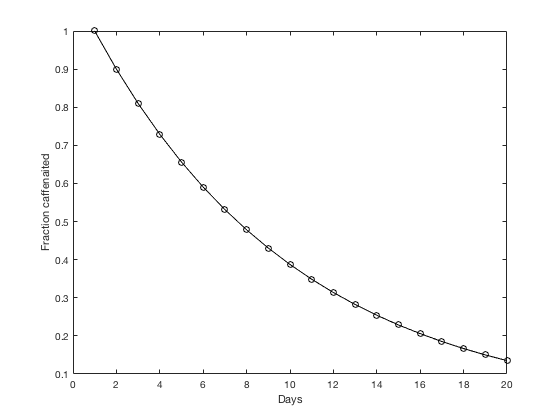

N = 10; % number of scoops in each jar
nMax = 2*N; % max number of days to simulate
x = ones(1,nMax); % fraction caffenaited
x(1) = 1.0; % initial fraction caffenaited

for n=2:nMax
    
    x(n) = (1-1/N)*x(n-1);
    
end % finished loop through days

figure;
plot(x,'-ok');
ylabel('Fraction caffenaited');
xlabel('Days');

 - Sometimes simulation gives unexpected results, i.e., our brains are not always good simulators.

 - Models have assumptions that are wrong.

# 1. Functions of a continuous variable

## 1.1 Functions

Let u(t) be the fluorescence signal from a microscope at time t, with t in seconds:

- u(t) = A sin(omega t).

- Functions are black boxes you feed an input and get an output.

- Two ways to define a function: in-line u=@(t)t^2 and in a separate m-file function

%% Define a function in-line
% u=@(t) A*sin(omega*t) + A_0;

u=@(t,A,omega,A_0) A*sin(omega*t) + A_0;
display(u(0.1,1.1,2.6,0.01)); % t=0.1, A=1.1, omega=2.6, A_0=0.01

    0.2928



A     = 1.1; % fluorescence intensity units
omega = 2.6; % rad/s
A_0   = 0.01;
u=@(t) A*sin(omega*t)+A_0;

display(u(0.1));

    0.2928



## a function defined in a separate m-file

There is a file in this directory called uBlackBox.m that defines a function

display(uBlackBox(0.1));

    0.7760



## 1.1.1 Functions versus an array of samples

Function on a continuous set (can't be plotted directly) versus array of samples u(tArray) (which can be plotted)

tArray = linspace(0,1.6,200);

tArray =          0    0.0080    0.0161    0.0241    0.0322    0.0402    0.0482    0.0563    0.0643    0.0724    0.0804    0.0884    0.0965    0.1045    0.1126    0.1206    0.1286    0.1367    0.1447    0.1528    0.1608    0.1688    0.1769    0.1849    0.1930    0.2010    0.2090    0.2171    0.2251    0.2332    0.2412    0.2492    0.2573    0.2653    0.2734    0.2814    0.2894    0.2975    0.3055    0.3136    0.3216    0.3296    0.3377    0.3457    0.3538    0.3618    0.3698    0.3779    0.3859    0.3940


uArray = u(tArray); % an array of samples of u

uArray =     0.0100    0.0330    0.0560    0.0789    0.1019    0.1248    0.1476    0.1704    0.1931    0.2157    0.2383    0.2607    0.2831    0.3053    0.3274    0.3493    0.3711    0.3927    0.4142    0.4355    0.4566    0.4775    0.4982    0.5187    0.5390    0.5591    0.5789    0.5984    0.6177    0.6368    0.6555    0.6740    0.6922    0.7101    0.7276    0.7449    0.7619    0.7785    0.7948    0.8107    0.8263    0.8415    0.8564    0.8709    0.8850    0.8988    0.9121    0.9251    0.9376    0.9498



figure; hold on;
plot(tArray,uArray);
ylabel('u');
xlabel('t');

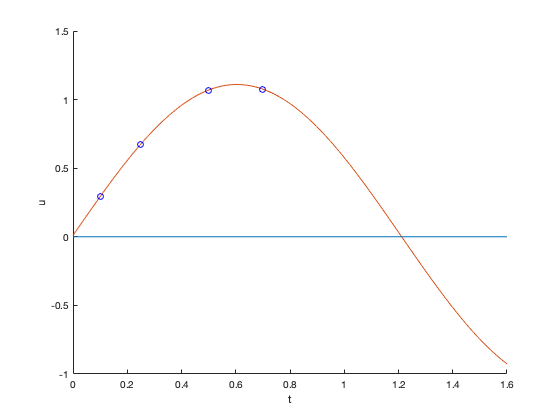

tArrayCoarse = [0.1 0.25 0.5 0.7];
uArrayCoarse = u(tArrayCoarse);

plot(tArray,uArray);
plot(tArrayCoarse, uArrayCoarse, 'ob')
refline(0,0); % add horizontal line at u=0

## 1.1.2 Where is a function zero? Symbolic, graphical, numerical: fzero, numerical from sample

Symbolicaly, we know the function u(t) is zero when $\sin(\omega*t) = - A_0/A$, so $t = 1/\omega*\rm{asin}(-A_0/A)$.

display(1/omega*asin(-A_0/A));

   -0.0035



display(1/omega*(pi-asin(-A_0/A)));

    1.2118



Graphically, we see it is around t=1.2s. 

Numerically, given the function:

tZero = fzero(u,1.2);
display(tZero);

tZero = 1.2118

Numerically, from the sample:

[minimalValue, indexOfMin] = min( (uArray - 0).^2 );
display(tArray(indexOfMin));

    1.2141

